# **Matlab案例代码解析**

## 2. 典型绘图案例

### 2.7 知乎提问

#### 2.7.10 在大圆当中生成若干个小圆

颜值即正义；

**颜色模板参考：**[**60套优雅的颜色模板**](https://zhuanlan.zhihu.com/p/444970597)

原问题：[https://www.zhihu.com/question/533562656/answer/2494541894](https://www.zhihu.com/question/533562656/answer/2494541894)

# 怎样用MATLAB在大圆当中生成若干个小圆？

输入大圆的半径，坐标（0，0），和小圆的个数，小圆的半径。

输出小圆的坐标。（要求所有小圆不相交，不相切）

思路：

- 用 rectangle 函数产生圆；

- 判断新产生的圆和之前产生的所有圆是否满足条件；

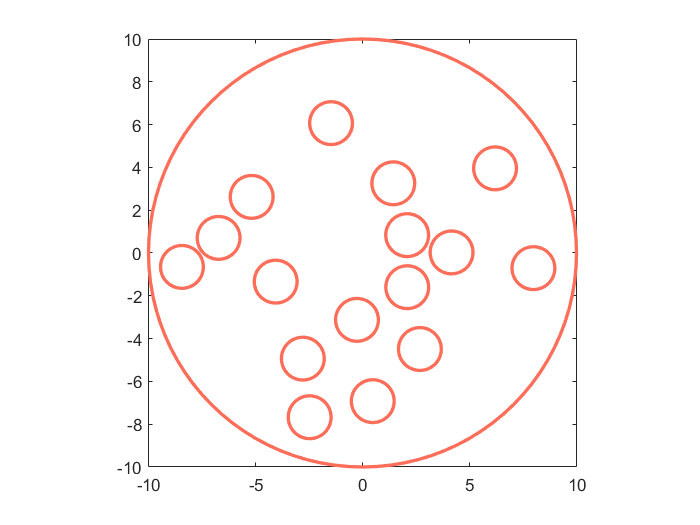

clear;clc;close all;
% 获取到颜色
[all_themes, all_colors] = GetColors(); 
% 限定范围
R = 10;
% 最多产生的圆的个数
circleNumber = 30;   
% 记录每个圆的横坐标、纵坐标、半径
% 小圆半径
r = 1;
paras = zeros(circleNumber, 3);  
num = 0;
rectangle('Position', [-R, -R, 2*R, 2*R], 'Curvature', [1 1], 'EdgeColor', all_colors(1, :), 'LineWidth', 2);
hold on
while num < circleNumber
    num = num + 1;    
    % 在范围内随机坐标
    theta = 2*pi*rand;
    xPos = (R - r) * cos(theta) * rand;  
    yPos = (R - r) * sin(theta) * rand;
    % 记录坐标、半径
    paras(num, :) = [xPos, yPos, r];
    % 判断每个圆的位置是否不相切、不相交
    if num > 1
        % 新产生的圆和之前产生的所有圆计算距离        
        xs = paras(1:num - 1, 1);
        ys = paras(1:num - 1, 2);
        dist = sqrt((xPos - xs).^2 + (yPos - ys).^2);
        % 如果相离则绘制当前产生的圆，否则就重新生成一个圆
        if all(dist > 2*r)
            rectangle('Position', [xPos-r, yPos-r, 2*r, 2*r], 'Curvature', [1 1], 'EdgeColor', all_colors(1, :), 'LineWidth', 2);
            axis equal
        else
            theta = 2*pi*rand;
            xPos = (R - r) * cos(theta) * rand;  
            yPos = (R - r) * sin(theta) * rand;
            paras(num, :) = [xPos, yPos, r];
            % 防止死循环
            temp = 0;
            maxTry = 100;
            while any(dist <= 2*r) && temp < maxTry
                temp = temp + 1;
                dist = sqrt((xPos - xs).^2 + (yPos - ys).^2);
            end
            if all(dist > 2*r)
                rectangle('Position', [xPos-r, yPos-r, 2*r, 2*r], 'Curvature', [1 1], 'EdgeColor', all_colors(1, :), 'LineWidth', 2);
                axis equal
            end
        end      
    end
end
box on
axis([-R R -R R])
hold off